% Problem 4: Exponential Fit (linearized)
time = [0, 0.21, 0.41, 0.62, 0.83, 1.03, 1.24, 1.45, 1.66, 1.86,...
        2.07, 2.28, 2.48, 2.69, 2.90, 3.10, 3.31, 3.52, 3.72, 3.93,...
        4.14, 4.34, 4.55, 4.76, 4.97, 5.17, 5.38, 5.59, 5.79, 6.00];
pop = [-3.02, 21.99, 3.87, -5.94, 13.58, 28.07, 52.56, 63.69, 74.90, 105.92,...
       130.39, 177.35, 210.67, 268.66, 319.96, 401.92, 486.04, 578.65, 698.98,...
       844.17, 1005.58, 1211.93, 1475.16, 1795.48, 2201.16, 2692.78, 3287.16,...
       4031.50, 4938.22, 6034.13];

% Remove negative values for log transformation
mask = pop > 0;
x = time(mask);
y = log(pop(mask));

% Fit linear model to log(y)
coeffs = polyfit(x, y, 1);
a = exp(coeffs(2));
b = coeffs(1);

% Compute predictions and R^2
y_fit = a * exp(b * time);
SStot = sum((pop - mean(pop)).^2);
SSres = sum((pop - y_fit).^2);
Rsq = 1 - SSres / SStot;

% Display results
fprintf('Problem 4 Best fit function: %.2f * exp(%.2f * x)\n', a, b);

Problem 4 Best fit function: 10.76 * exp(1.09 * x)


fprintf('R squared value: %.4f\n', Rsq);

R squared value: 0.9399


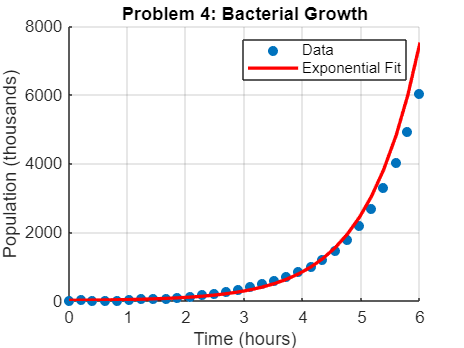


% Plot
figure;
scatter(time, pop, 'filled'); hold on;
plot(time, y_fit, 'r', 'LineWidth', 2);
title('Problem 4: Bacterial Growth');
xlabel('Time (hours)');
ylabel('Population (thousands)');
legend('Data', 'Exponential Fit');
grid on;